# Modelagem e Controle conversor Cuk

#### Modelagem e Controle do Conversor Cuk - Espaço de Estados e Projeto de Controladores PI

clear; clc; close all;

### **Cuk ideal**

% Variáveis de estado
syms d Vi C1 C2 L1 L2 Ro s

% 1a e 2a etapa
% ic = il - io
%filtrar ondulacao da corrente do indutor

% il - io / delta_il/2 
% area do triangulo : b*2/2 .
% deltaq = c * DELTA_VO
% DELTAQ = (TS/2 * DELTA_IL/2)/2
U = [Vi; 0; 0; 0];

AA1 = [0 0 0 0 ;
        0 0 1/L2 -1/L2; 
        0 -1/C1 0 0;
        0 1/C2 0 -1/(Ro*C2)];

AA2 = [0 0 -1/L1 0;
        0 0 0 -1/L2;
        1/C1 0 0 0;
        0 1/C2 0 -1/(Ro*C2)];

AA = simplify(AA1*d+AA2*(1-d));
A = AA;

BB1= [1/L1  0     0      0;
    0      0     0      0;
    0      0     0      0;
    0      0     0      0];
BB2=BB1;

BB = simplify((BB1*d)+(BB2*(1-d)));
B=BB;

% CC MODEL - operation point behaviour
X = - simplify(inv(AA)*BB)*U ;

% Transfer function
E1 = ( AA1 - AA2)*X

$$E1 = \left(\begin{array}{c} -\frac{\mathrm{Vi}}{L_{1}\,\left(d-1\right)}\\ -\frac{\mathrm{Vi}}{L_{2}\,\left(d-1\right)}\\ \frac{\mathrm{Vi}\,d}{C_{1}\,\mathrm{Ro}\,\left(d-1\right)}-\frac{\mathrm{Vi}\,d^{2}}{C_{1}\,\mathrm{Ro}\,{\left(d-1\right)}^{2}}\\ 0 \end{array}\right)$$

E2 = simplify((BB1-BB2)*U)

$$E2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

E = simplify(E1+E2)

$$E = \left(\begin{array}{c} -\frac{\mathrm{Vi}}{L_{1}\,\left(d-1\right)}\\ -\frac{\mathrm{Vi}}{L_{2}\,\left(d-1\right)}\\ -\frac{\mathrm{Vi}\,d}{C_{1}\,\mathrm{Ro}\,{\left(d-1\right)}^{2}}\\ 0 \end{array}\right)$$


%MATRIZES DE SAÍDA
C_vod = [0, 0, 0, 1];     % tensão de saída
C_iLd = [1, 0, 0, 0];    % corrente no indutor L1

%colect isola variavel, ex em funcao de s
Gvod = collect(simplify(C_vod *inv(s*eye(4)-AA)*E), s)

$$Gvod = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

GiLd = collect(simplify(C_vod *inv(s*eye(4)-AA)*E), s)

$$GiLd = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$


% y / d
G_vo_d = C_vod / (s * eye(4) - AA) * [E];
G_vo_d = collect(simplify(G_vo_d), s)

$$G\_vo\_d = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$


% IL / d
G_iL_d = C_iLd / (s * eye(4) - AA) * [E];
G_iL_d = collect(simplify(G_iL_d), s)

$$G\_iL\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$


fprintf('FUNÇÕES DE TRANSFERÊNCIA:\n');

FUNÇÕES DE TRANSFERÊNCIA:



fprintf('Gvd(s) = vo(s)/d(s):\n');

Gvd(s) = vo(s)/d(s):


G_vo_d

$$G\_vo\_d = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

fprintf('\nGiL1d(s) = iL1(s)/d(s):\n');


GiL1d(s) = iL1(s)/d(s):


G_iL_d

$$G\_iL\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

#### Cuk não ideal

syms Vin C1 C2 L1 L2 Vo IL1 IL2 dil2 vs Vf Vi rL  Ro rS rD rC rC1 rC2 rLn Vc1 Vc2 VF dvc1 dvo s D

%% MATRIZES DAS ETAPAS 1 E 2
% Modo S = ON (DTs)
A1 = [ -(rL + rS)/L1,   0,               -rS/L1,           0;
       0,                 0,               -1/C1,            0;
       -rS/L2,            1/L2,            -(rL + rC + rS)/L2,   -1/L2;
       0,                 0,               1/C2,            -1/(C2*Ro) ];
B1 = [ 1/L1; 0; 0; 0 ];

% Modo S = OFF (1-D)Ts
A2 = [ -(rL + rC + rD)/L1,   -1/L1,            -rD/L1,           0;
       1/C1,                    0,                0,                0;
       -rD/L2,                  0,                -(rL + rD)/L2,   -1/L2;
       0,                       0,                1/C2,            -1/(C2*Ro) ];
B2 = [ 1/L1; 0; 0; 0 ];

% (1-D)*I_L1 = D*I_L2
IL1 = (D/(1-D)) * IL2;
IL2 = Vo / Ro;

% Coeficientes auxiliares
a1 = rL + D*rS + (1-D)*rD;          % para iL1
a2 = D*rS + (1-D)*rD;                % termo cruzado iL1-iL2
b1 = D*(rL + rC + rS) + (1-D)*(rLn + rD);  % para iL2

V_C1 = (Vin - a1*IL1 - a2*IL2 - (1-D)*VF) / (1-D);
eq3 = -a2*IL1 + D*V_C1 - b1*IL2 - Vo - (1-D)*VF;

fprintf('PONTO DE EQUILÍBRIO:\n');

PONTO DE EQUILÍBRIO:


fprintf('--------------------\n');

--------------------


fprintf('IL1 = ');

IL1 = 

disp(IL1);

$$-\frac{\text{D}\,{\mathrm{IL}}_{2}}{\text{D}-1}$$

fprintf('A\n IL2 =  ' );

A
 IL2 =  

disp(IL2);

$$\frac{\mathrm{Vo}}{\mathrm{Ro}}$$

fprintf('A \n V_C1 = ');

A 
 V_C1 = 

disp(V_C1);

$$-\frac{\mathrm{Vin}+\mathrm{VF}\,\left(\text{D}-1\right)-\frac{\mathrm{Vo}\,\left(\text{D}\,\mathrm{rS}-\mathrm{rD}\,\left(\text{D}-1\right)\right)}{\mathrm{Ro}}+\frac{\text{D}\,{\mathrm{IL}}_{2}\,\left(\mathrm{rL}+\text{D}\,\mathrm{rS}-\mathrm{rD}\,\left(\text{D}-1\right)\right)}{\text{D}-1}}{\text{D}-1}$$

fprintf('V \n V_o = ');

V 
 V_o = 

disp(Vo);

$$\mathrm{Vo}$$

fprintf('V\n');

V



%  MATRIZ A LINEARIZADA (média ponderada no ponto D)
A = D*A1 + (1-D)*A2;

fprintf('MATRIZ A (linearizada):\n');

MATRIZ A (linearizada):


disp(A);

$$\begin{array}{l} \left(\begin{array}{cccc} \frac{\left(\text{D}-1\right)\,\left(\mathrm{rC}+\mathrm{rD}+\mathrm{rL}\right)}{L_{1}}-\frac{\text{D}\,\left(\mathrm{rL}+\mathrm{rS}\right)}{L_{1}} & \frac{\text{D}-1}{L_{1}} & \frac{\sigma_{1}}{L_{1}}-\frac{\text{D}\,\mathrm{rS}}{L_{1}} & 0\\ -\frac{\text{D}-1}{C_{1}} & 0 & -\frac{\text{D}}{C_{1}} & 0\\ \frac{\sigma_{1}}{L_{2}}-\frac{\text{D}\,\mathrm{rS}}{L_{2}} & \frac{\text{D}}{L_{2}} & \frac{\left(\mathrm{rD}+\mathrm{rL}\right)\,\left(\text{D}-1\right)}{L_{2}}-\frac{\text{D}\,\left(\mathrm{rC}+\mathrm{rL}+\mathrm{rS}\right)}{L_{2}} & \frac{\text{D}-1}{L_{2}}-\frac{\text{D}}{L_{2}}\\ 0 & 0 & \frac{\text{D}}{C_{2}}-\frac{\text{D}-1}{C_{2}} & \frac{\text{D}-1}{C_{2}\,\mathrm{Ro}}-\frac{\text{D}}{C_{2}\,\mathrm{Ro}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{rD}\,\left(\text{D}-1\right) \end{array}$$


% F = (A1 - A2)*X + (B1 - B2)*Vin
X = [IL1; V_C1; IL2; Vo];

A1_minus_A2 = A1 - A2;
B1_minus_B2 = B1 - B2;

F = A1_minus_A2 * X + B1_minus_B2 * Vin;

fprintf('VETOR F:\n');

VETOR F:


disp(F);

$$\begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Vo}\,\left(\frac{\mathrm{rD}}{L_{1}}-\frac{\mathrm{rS}}{L_{1}}\right)}{\mathrm{Ro}}-\frac{\sigma_{1}}{L_{1}\,\left(\text{D}-1\right)}+\frac{\text{D}\,{\mathrm{IL}}_{2}\,\left(\frac{\mathrm{rL}+\mathrm{rS}}{L_{1}}-\frac{\mathrm{rC}+\mathrm{rD}+\mathrm{rL}}{L_{1}}\right)}{\text{D}-1}\\ \frac{\text{D}\,{\mathrm{IL}}_{2}}{C_{1}\,\left(\text{D}-1\right)}-\frac{\mathrm{Vo}}{C_{1}\,\mathrm{Ro}}\\ \frac{\mathrm{Vo}\,\left(\frac{\mathrm{rD}+\mathrm{rL}}{L_{2}}-\frac{\mathrm{rC}+\mathrm{rL}+\mathrm{rS}}{L_{2}}\right)}{\mathrm{Ro}}-\frac{\sigma_{1}}{L_{2}\,\left(\text{D}-1\right)}-\frac{\text{D}\,{\mathrm{IL}}_{2}\,\left(\frac{\mathrm{rD}}{L_{2}}-\frac{\mathrm{rS}}{L_{2}}\right)}{\text{D}-1}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Vin}+\mathrm{VF}\,\left(\text{D}-1\right)-\frac{\mathrm{Vo}\,\left(\text{D}\,\mathrm{rS}-\sigma_{2}\right)}{\mathrm{Ro}}+\frac{\text{D}\,{\mathrm{IL}}_{2}\,\left(\mathrm{rL}+\text{D}\,\mathrm{rS}-\sigma_{2}\right)}{\text{D}-1}\\ \sigma_{2}=\mathrm{rD}\,\left(\text{D}-1\right) \end{array}$$


%MATRIZES DE SAÍDA
CC1 = [0, 0, 0, 1];     % tensão de saída
CC2 = [1, 0, 0, 0];    % corrente no indutor L1
Dmat = 0;
% 

%  PONTO DE EQUILÍBRIO
% (1-D)*I_L1 = D*I_L2
IL1 = (D/(1-D)) * IL2;
% I_L2 = Vo / Ro
IL2 = Vo / Ro;

% Coeficientes auxiliares
a1 = rL + D*rS + (1-D)*rD;          % para iL1
a2 = D*rS + (1-D)*rD;                % termo cruzado iL1-iL2
b1 = D*(rL + rC + rS) + (1-D)*(rL + rD);  % para iL2

% Equação (1): V_C1
V_C1 = (Vin - a1*IL1 - a2*IL2 - (1-D)*VF) / (1-D);

% Verificação da equação (3)
eq3 = -a2*IL1 + D*V_C1 - b1*IL2 - Vo - (1-D)*VF;

fprintf('PONTO DE EQUILÍBRIO:\n');

PONTO DE EQUILÍBRIO:


IL1

$$IL1 = -\frac{\text{D}\,\mathrm{Vo}}{\mathrm{Ro}\,\left(\text{D}-1\right)}$$

IL2

$$IL2 = \frac{\mathrm{Vo}}{\mathrm{Ro}}$$

V_C1

$$V\_C1 = -\frac{\mathrm{Vin}+\mathrm{VF}\,\left(\text{D}-1\right)-\frac{\mathrm{Vo}\,\left(\text{D}\,\mathrm{rS}-\mathrm{rD}\,\left(\text{D}-1\right)\right)}{\mathrm{Ro}}+\frac{\text{D}\,\mathrm{Vo}\,\left(\mathrm{rL}+\text{D}\,\mathrm{rS}-\mathrm{rD}\,\left(\text{D}-1\right)\right)}{\mathrm{Ro}\,\left(\text{D}-1\right)}}{\text{D}-1}$$

Vo

$$Vo = \mathrm{Vo}$$

eq3

$$eq3 = \begin{array}{l} \sigma_{1}-\mathrm{Vo}-\frac{\text{D}\,\left(\mathrm{Vin}+\sigma_{1}-\frac{\mathrm{Vo}\,\sigma_{3}}{\mathrm{Ro}}+\frac{\text{D}\,\mathrm{Vo}\,\left(\mathrm{rL}+\text{D}\,\mathrm{rS}-\sigma_{4}\right)}{\sigma_{2}}\right)}{\text{D}-1}+\frac{\mathrm{Vo}\,\left(\left(\mathrm{rD}+\mathrm{rL}\right)\,\left(\text{D}-1\right)-\text{D}\,\left(\mathrm{rC}+\mathrm{rL}+\mathrm{rS}\right)\right)}{\mathrm{Ro}}+\frac{\text{D}\,\mathrm{Vo}\,\sigma_{3}}{\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{VF}\,\left(\text{D}-1\right)\\ \sigma_{2}=\mathrm{Ro}\,\left(\text{D}-1\right)\\ \sigma_{3}=\text{D}\,\mathrm{rS}-\sigma_{4}\\ \sigma_{4}=\mathrm{rD}\,\left(\text{D}-1\right) \end{array}$$



% vo / d
G_vo_non_ideal  = CC1 / (s * eye(4) - AA) * [E];
G_vo_d_non_ideal = collect(simplify(G_vo_non_ideal), s)

$$G\_vo\_d\_non\_ideal = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

% iL / d
G_iLd_non_ideal = CC2 / (s * eye(4) - AA) * [E];
G_iL_d_non_ideal = collect(simplify(G_iLd_non_ideal), s)

$$G\_iL\_d\_non\_ideal = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$


% sys_vo = ss(A, F, C_vo, Dmat);
% sys_iL1 = ss(A, F, C_iL1, Dmat);
% Gvd = tf(sys_vo);
% GiL1d = tf(sys_iL1);

fprintf('FUNÇÕES DE TRANSFERÊNCIA:\n');

FUNÇÕES DE TRANSFERÊNCIA:



fprintf('Gvd(s) = vo(s)/d(s):\n');

Gvd(s) = vo(s)/d(s):


G_vo_d_non_ideal

$$G\_vo\_d\_non\_ideal = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

fprintf('\nGiL1d(s) = iL1(s)/d(s):\n');


GiL1d(s) = iL1(s)/d(s):


G_iL_d_non_ideal

$$G\_iL\_d\_non\_ideal = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

#### DADOS CONVERSOR

**Dados conversor**

Vin = 48;           % Tensão de entrada (V)
Vo = 72;            % Tensão de saída (V)
delta_iL = 0.2; delta_I_L_p = delta_iL;    % Variação da corrente (relativa)
delta_vC1 = 0.2; delta_V_C1_p = delta_vC1;   % Variação da tensão C1 (relativa)
delta_Vo = 0.05;    % Variação da tensão de saída (relativa)
fs = 50e3;          % Frequência de comutação (Hz)
Po = 300;           % Potência de saída (W)
fr = 60; fg=fr;           % Frequência da rede [Hz]

D_val = Vo / (Vin + Vo); % Cuk/sepic duty cycle formula
D=D_val;

Ts = (1/fs) ; % secs
Vs  = Vin*D_val/(1-D_val);

Io = Po/Vo ;
Iin = Po/Vin ;
IL1_val = Iin; I_l1 = IL1_val;

IL2_val = Io;I_l2= IL2_val;
Rload = Vo/Io;       % load resistance (Ohm)
Rload2 = (Vo^2) / Po;

%delta_Q = C * delta_Vo
Vrms = sqrt(Vin);
Vpeak = Vrms * sqrt(2);
Amplitude = Vpeak;

delta_I_l1 = I_l1 * delta_I_L_p ;
delta_I_l2 = I_l2 * delta_I_L_p ;

L1_val = (Vin*(D))/(delta_I_l1*fs) ;
L2_val = (Vo*(1-D))/(delta_I_l2*fs) ;

delta_V_C1 = Vin * delta_V_C1_p; 
delta_V_C2 = Vo * delta_Vo; 

C1_val = (Io * D) / (delta_V_C1 * fs);       % Capacitor C1 (F)
C2_val = (Vo * (1-D)) / (8 * delta_V_C2 * fs^2 * L2_val)       % Capacitor C2 (F)

C2_val = 5.7870e-07



delta_Q = (Ts/2 * delta_I_L_p/2)/2;
C = delta_Vo/delta_Q ;

VFn = 1 ; % V



#### Função de transferência

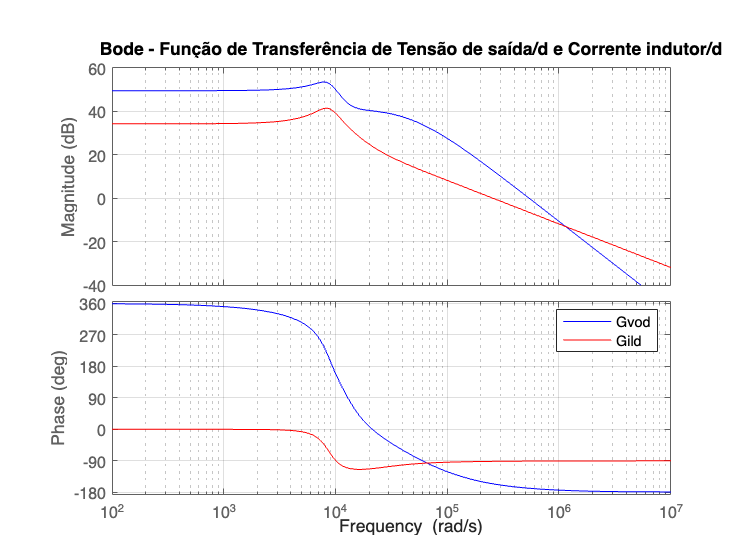


% Definindo os valores reais
valores = [C1, C2, L1, L2, Ro, Vi, d]; %simbolic
numeros = [C1_val, C2_val, L1_val, L2_val,  Rload, Vin,  D]; % Exemplo de valores

% Substituição (exceto o 's')
Gvo_num_sym = subs(G_vo_d, valores, numeros);
G_iL_d_num_sym = subs(G_iL_d, valores, numeros);


% Separa numerador e denominador do resultado simbólico
[Num, Den] = numden(Gvo_num_sym);
[Num2, Den2] = numden(G_iL_d_num_sym);

% Converte os polinômios simbólicos em vetores numéricos de coeficientes
% O MATLAB extrai na ordem: [s^n, s^(n-1), ..., s^0]
num_vetor = double(sym2poly(Num));
den_vetor = double(sym2poly(Den));
num_vetor2 = double(sym2poly(Num2));
den_vetor2 = double(sym2poly(Den2));

% Se o ganho ficar muito alto no numerador, pode ser necessário normalizar
% dividindo ambos pelo primeiro termo do denominador:
num_vetor = num_vetor / den_vetor(1);
den_vetor = den_vetor / den_vetor(1);

num_vetor2 = num_vetor2 / den_vetor2(1);
den_vetor2 = den_vetor2 / den_vetor2(1);


% Cria a Função de Transferência Numérica
sys = tf(num_vetor, den_vetor);
sys_iL = tf(num_vetor2, den_vetor2);
%sys = tf(num, den);



figure;
bode(sys, 'b-', sys_iL, 'r-') %, G3, 'g-', G4, 'm-');
grid on;
legend('Gvod', 'Gild', ...
       'Location', 'northeast');
%title('GVod GiLd');
title('Bode - Função de Transferência de Tensão de saída/d e Corrente indutor/d');
grid on;



FT_G_Vod=sys;
% Exibir a função de transferência
disp('Função de transferência: G(s) = Vo/d');

Função de transferência: Gvod


disp(FT_G_Vod);

  tf with properties:

       Numerator: {[0 0 3.0000e+11 -3.0000e+15 5.0000e+19]}
     Denominator: {[1 1.0000e+05 2.6667e+09 1.6667e+13 1.6667e+17]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



FT_G_iLd=sys_iL;
% Exibir a função de transferência
disp('Função de transferência: G(s) = iL/d');

Função de transferência: GiLd


disp(FT_G_iLd);

  tf with properties:

       Numerator: {[0 2.6042e+05 2.7778e+10 8.6806e+14 8.6806e+18]}
     Denominator: {[1 1.0000e+05 2.6667e+09 1.6667e+13 1.6667e+17]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



####  PROJETO DO CONTROLADOR PI PARA A MALHA DE CORRENTE (iL1)

% Ganhos dos sensores e PWM
Ki = 1;             % Ganho do sensor de corrente

% Io/Vo
Kv = 4 / 72;             % Ganho do sensor de tensão
KPWM = 1/5;           % Ganho do modulador PWM(pico de 5V)


omega_r = 2 * pi * fr;          % Frequência angular da rede [rad/s]
omega_s = 2 * pi * fs;           % Frequência angular de comutação [rad/s]
I_rms = Po / Vrms;               % Corrente eficaz nominal [A]

% Frequência de ressonância entre 10*fr e fs/10
fres = 100 * fr;
omega_res = 2*pi*fres;

fprintf('Frequência angular da rede: %.2f rad/s\n', omega_r);

Frequência angular da rede: 376.99 rad/s


fprintf('Frequência angular de comutação: %.2f rad/s\n', omega_s);

Frequência angular de comutação: 314159.27 rad/s


fprintf('Corrente eficaz nominal: %.2f A\n', I_rms);

Corrente eficaz nominal: 43.30 A





fprintf(' PROJETO DO CONTROLADOR PI - MALHA DE CORRENTE (iL1)\n');

 PROJETO DO CONTROLADOR PI - MALHA DE CORRENTE (iL1)



% Especificações da malha de corrente
wc_i = 12560;               % Frequência de cruzamento (rad/s) - 2 kHz
MF_i = 60 * pi/180;         % Margem de fase desejada (60° em radianos)

% Função de transferência de malha aberta não compensada
FTLA_NC_i = FT_G_iLd * Ki * KPWM;

% Calcular magnitude e fase na frequência de cruzamento
[mag_i, phase_i, ~] = bode(FTLA_NC_i, wc_i);
mag_i_abs = mag_i(1);
phase_i_deg = phase_i(1);
phase_i_rad = phase_i_deg * pi/180;

fprintf('Em ωc = %.2f rad/s (%.2f Hz):\n', wc_i, wc_i/(2*pi));

Em ωc = 12560.00 rad/s (1998.99 Hz):


fprintf('  |FTLA_NC| = %.2f dB (%.4e linear)\n', 20*log10(mag_i_abs), mag_i_abs);

  |FTLA_NC| = 19.83 dB (9.8006e+00 linear)


fprintf('  ∠FTLA_NC = %.2f° (%.4f rad)\n', phase_i_deg, phase_i_rad);

  ∠FTLA_NC = -109.68° (-1.9144 rad)



% Cálculo do zero do controlador (ωz)
tan_arg_i = tan(MF_i - pi/2 - phase_i_rad);

if tan_arg_i > 0
    wz_i = wc_i / tan_arg_i;
else
    wz_i = wc_i / 10;
    fprintf('  Atenção: tan_arg = %.4f, usando wz_i = %.2f rad/s\n', tan_arg_i, wz_i);
end

if wz_i <= 0
    wz_i = wc_i / 10;
    fprintf('  Ajuste: wz_i = %.2f rad/s\n', wz_i);
end

% Cálculo do ganho do controlador (kc)
kc_i = wc_i / (sqrt(wc_i^2 + wz_i^2) * mag_i_abs);

fprintf('\nPARÂMETROS DO CONTROLADOR PI (CORRENTE):\n');


PARÂMETROS DO CONTROLADOR PI (CORRENTE):


fprintf('  ωz = %.2f rad/s (fz = %.2f Hz)\n', wz_i, wz_i/(2*pi));

  ωz = 2286.00 rad/s (fz = 363.83 Hz)


fprintf('  τz = 1/ωz = %.4f s\n', 1/wz_i);

  τz = 1/ωz = 0.0004 s


fprintf('  kc = %.4e\n', kc_i);

  kc = 1.0039e-01



% Controlador PI para a corrente
Ci = tf(kc_i * [1, wz_i], [1, 0]);

fprintf('  C_i(s) = %.4e * (s + %.2f) / s\n', kc_i, wz_i);

  C_i(s) = 1.0039e-01 * (s + 2286.00) / s


fprintf('  C_i(s) = %.4e + %.4e / s\n', kc_i, kc_i * wz_i);

  C_i(s) = 1.0039e-01 + 2.2948e+02 / s



% Função de transferência de malha aberta compensada
FTLA_C_i = FTLA_NC_i * Ci;

% Margens de estabilidade
[Gm_i, Pm_i, Wcg_i, Wcp_i] = margin(FTLA_C_i);

fprintf('\nMARGENS DE ESTABILIDADE (MALHA DE CORRENTE):\n');


MARGENS DE ESTABILIDADE (MALHA DE CORRENTE):


fprintf('  Margem de ganho:  %.2f dB\n', 20*log10(Gm_i));

  Margem de ganho:  Inf dB


fprintf('  Margem de fase:   %.2f°\n', Pm_i);

  Margem de fase:   60.00°


fprintf('  Frequência de cruzamento de ganho: %.2f rad/s (%.2f Hz)\n', Wcp_i, Wcp_i/(2*pi));

  Frequência de cruzamento de ganho: 12560.32 rad/s (1999.04 Hz)



% Função de transferência de malha fechada (desacoplamento)
FTMF_i = Ci * KPWM * FT_G_iLd / (1 + Ki * Ci * KPWM * FT_G_iLd);

%% ========================================================================

###  PROJETO DO CONTROLADOR PI PARA A MALHA DE TENSÃO (vo)

fprintf(' PROJETO DO CONTROLADOR PI - MALHA DE TENSÃO (vo)\n');

 PROJETO DO CONTROLADOR PI - MALHA DE TENSÃO (vo)


 


% Especificações da malha de tensão
wc_v = 6280;                % Frequência de cruzamento (rad/s) - 1 kHz
MF_v = 60 * pi/180;         % Margem de fase desejada (60° em radianos)

% Função de transferência de malha aberta não compensada
FTLA_NC_v = FT_G_Vod * Kv * KPWM;

% Calcular magnitude e fase na frequência de cruzamento
[mag_v, phase_v, ~] = bode(FTLA_NC_v, wc_v);
mag_v_abs = mag_v(1);
phase_v_deg = phase_v(1);
phase_v_rad = phase_v_deg * pi/180;

fprintf('Em ωc = %.2f rad/s (%.2f Hz):\n', wc_v, wc_v/(2*pi));

Em ωc = 6280.00 rad/s (999.49 Hz):


fprintf('  |FTLA_NC| = %.2f dB (%.4e linear)\n', 20*log10(mag_v_abs), mag_v_abs);

  |FTLA_NC| = 13.34 dB (4.6466e+00 linear)


fprintf('  ∠FTLA_NC = %.2f° (%.4f rad)\n', phase_v_deg, phase_v_rad);

  ∠FTLA_NC = 282.01° (4.9220 rad)



% Cálculo do zero do controlador (ωz)
tan_arg_v = tan(MF_v - pi/2 - phase_v_rad);

if tan_arg_v > 0
    wz_v = wc_v / tan_arg_v;
else
    wz_v = wc_v / 10;
    fprintf('  Atenção: tan_arg = %.4f, usando wz_v = %.2f rad/s\n', tan_arg_v, wz_v);
end

if wz_v <= 0
    wz_v = wc_v / 10;
    fprintf('  Ajuste: wz_v = %.2f rad/s\n', wz_v);
end

% Cálculo do ganho do controlador (kc)
kc_v = wc_v / (sqrt(wc_v^2 + wz_v^2) * mag_v_abs);

fprintf('\nPARÂMETROS DO CONTROLADOR PI (TENSÃO):\n');


PARÂMETROS DO CONTROLADOR PI (TENSÃO):


fprintf('  ωz = %.2f rad/s (fz = %.2f Hz)\n', wz_v, wz_v/(2*pi));

  ωz = 5656.11 rad/s (fz = 900.20 Hz)


fprintf('  τz = 1/ωz = %.4f s\n', 1/wz_v);

  τz = 1/ωz = 0.0002 s


fprintf('  kc = %.4e\n', kc_v);

  kc = 1.5991e-01



% Controlador PI para a tensão
Cv = tf(kc_v * [1, wz_v], [1, 0]);

fprintf('  C_v(s) = %.4e * (s + %.2f) / s\n', kc_v, wz_v);

  C_v(s) = 1.5991e-01 * (s + 5656.11) / s


fprintf('  C_v(s) = %.4e + %.4e / s\n', kc_v, kc_v * wz_v);

  C_v(s) = 1.5991e-01 + 9.0448e+02 / s



% Função de transferência de malha aberta compensada
FTLA_C_v = FTLA_NC_v * Cv;

% Margens de estabilidade
[Gm_v, Pm_v, Wcg_v, Wcp_v] = margin(FTLA_C_v);

fprintf('\nMARGENS DE ESTABILIDADE (MALHA DE TENSÃO):\n');


MARGENS DE ESTABILIDADE (MALHA DE TENSÃO):


fprintf('  Margem de ganho:  %.2f dB\n', 20*log10(Gm_v));

  Margem de ganho:  0.16 dB


fprintf('  Margem de fase:   %.2f°\n', Pm_v);

  Margem de fase:   4.58°


fprintf('  Frequência de cruzamento de ganho: %.2f rad/s (%.2f Hz)\n', Wcp_v, Wcp_v/(2*pi));

  Frequência de cruzamento de ganho: 8364.02 rad/s (1331.18 Hz)


### Comparativo

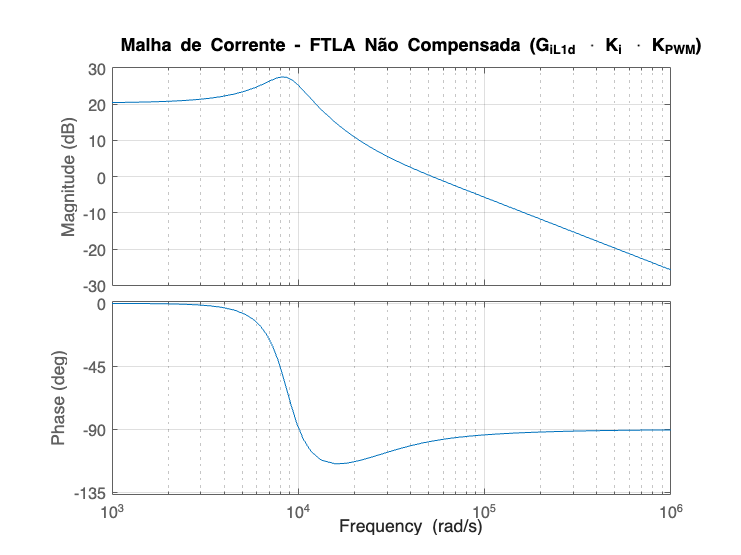

%  Bode da FTLA não compensada (corrente)
figure(1);
bode(FTLA_NC_i);
grid on;
title('Malha de Corrente - FTLA Não Compensada (G_{iL1d} \cdot K_i \cdot K_{PWM})');

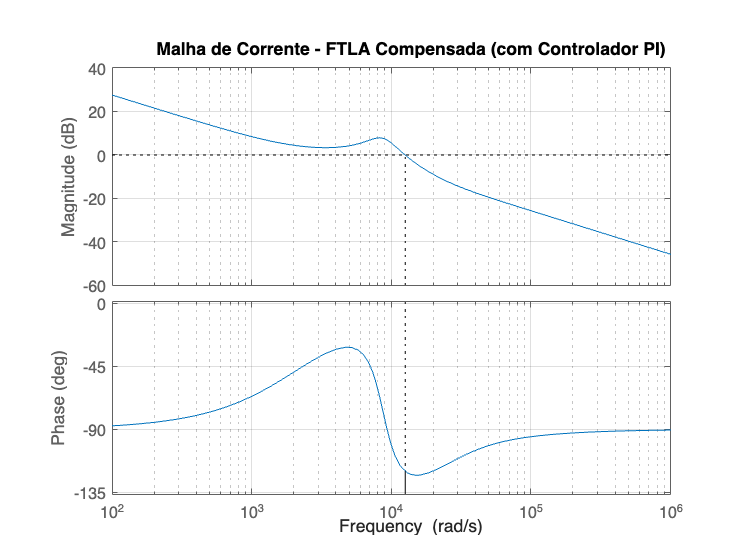


% Bode da FTLA compensada (corrente)
figure(2);
margin(FTLA_C_i);
grid on;
title('Malha de Corrente - FTLA Compensada (com Controlador PI)');

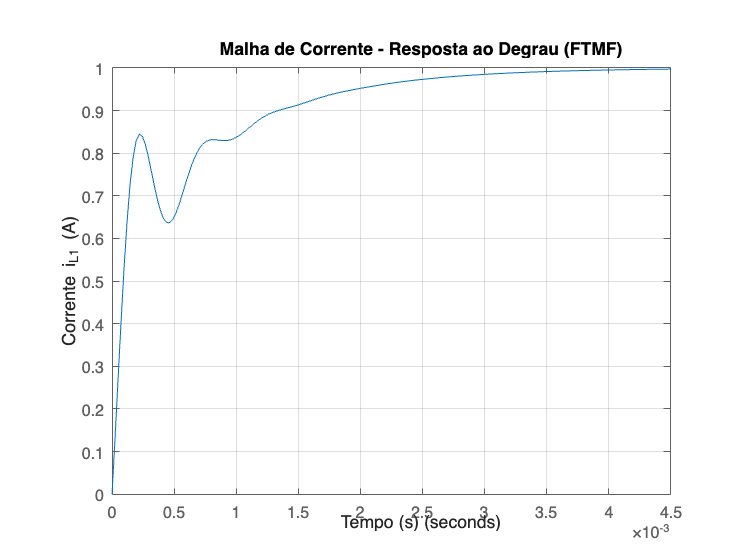


%  Resposta ao degrau da malha fechada (corrente)
figure(3);
step(FTMF_i);
grid on;
title('Malha de Corrente - Resposta ao Degrau (FTMF)');
xlabel('Tempo (s)');
ylabel('Corrente i_{L1} (A)');

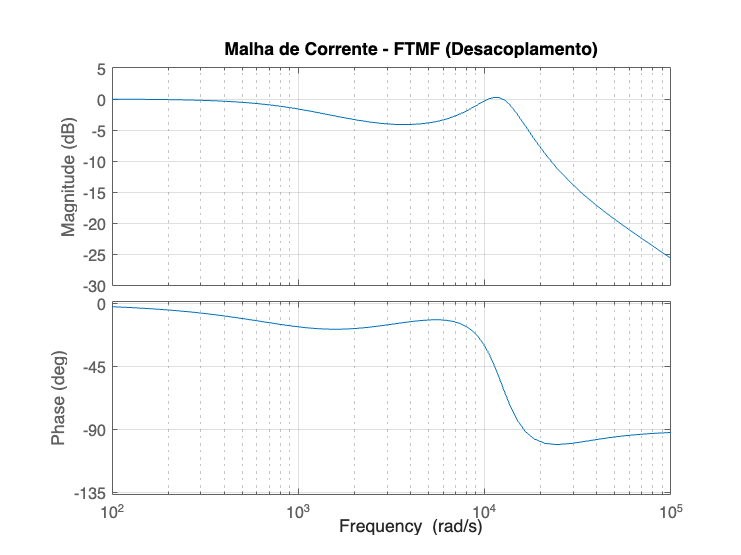


% Bode da FTMF (corrente)
figure(4);
bode(FTMF_i);
grid on;
title('Malha de Corrente - FTMF (Desacoplamento)');

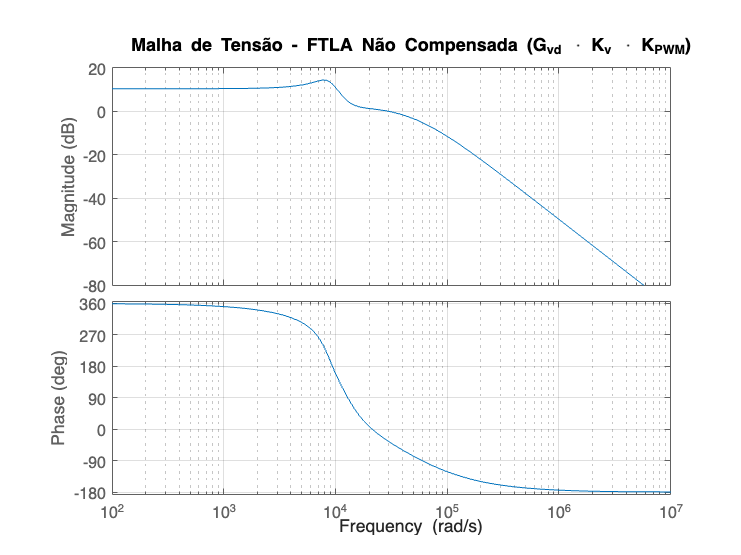


%%  GRÁFICOS - MALHA DE TENSÃO


% Bode da FTLA não compensada (tensão)
figure(5);
bode(FTLA_NC_v);
grid on;
title('Malha de Tensão - FTLA Não Compensada (G_{vd} \cdot K_v \cdot K_{PWM})');

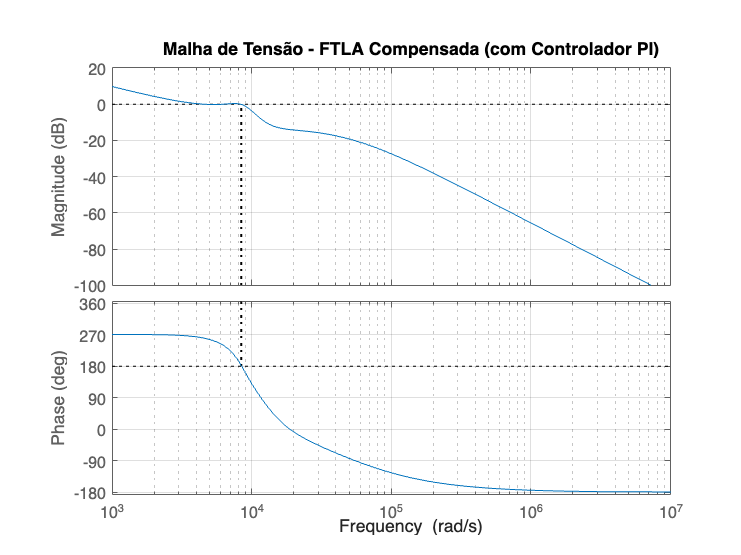


%  Bode da FTLA compensada (tensão)
figure(6);
margin(FTLA_C_v);
grid on;
title('Malha de Tensão - FTLA Compensada (com Controlador PI)');

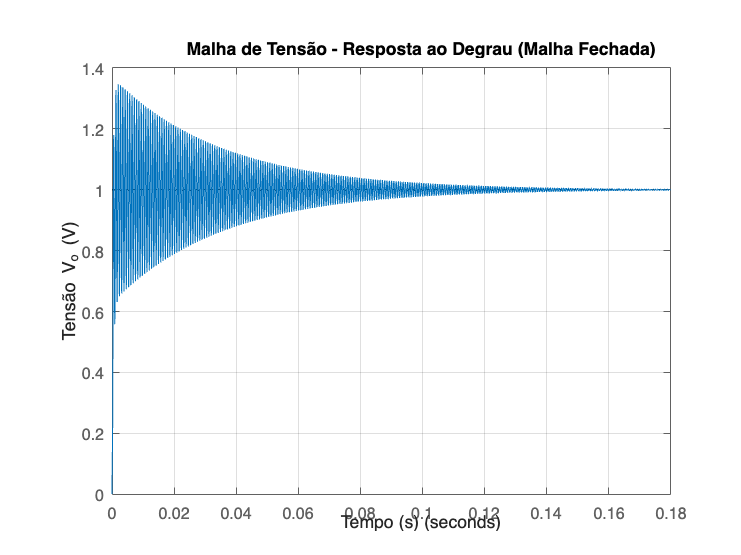


% Resposta ao degrau da malha fechada (tensão)
FTMF_v = feedback(FTLA_C_v, 1);
figure(7);
step(FTMF_v);
grid on;
title('Malha de Tensão - Resposta ao Degrau (Malha Fechada)');
xlabel('Tempo (s)');
ylabel('Tensão V_o (V)');


%%  SALVAR MODELO E CONTROLADORES
% 

save('modelo_cuk_completo.mat', 'FT_G_iLd', 'FT_G_iLd', 'A', 'F', 'Ci', 'Cv', ...
     'FTLA_C_i', 'FTLA_C_v', 'FTMF_i');


fprintf('Controlador de Corrente (iL1):\n');

Controlador de Corrente (iL1):


fprintf('  C_i(s) = %.4e * (s + %.2f) / s\n', kc_i, wz_i);

  C_i(s) = 1.0039e-01 * (s + 2286.00) / s


fprintf('  C_i(s) = %.4e + %.4e / s\n', kc_i, kc_i * wz_i);

  C_i(s) = 1.0039e-01 + 2.2948e+02 / s


fprintf('  ωc = %.2f rad/s (%.2f Hz)\n', wc_i, wc_i/(2*pi));

  ωc = 12560.00 rad/s (1998.99 Hz)


fprintf('  MF  = %.2f°\n', Pm_i);

  MF  = 60.00°


fprintf('\nControlador de Tensão (vo):\n');


Controlador de Tensão (vo):


fprintf('  C_v(s) = %.4e * (s + %.2f) / s\n', kc_v, wz_v);

  C_v(s) = 1.5991e-01 * (s + 5656.11) / s


fprintf('  C_v(s) = %.4e + %.4e / s\n', kc_v, kc_v * wz_v);

  C_v(s) = 1.5991e-01 + 9.0448e+02 / s


fprintf('  ωc = %.2f rad/s (%.2f Hz)\n', wc_v, wc_v/(2*pi));

  ωc = 6280.00 rad/s (999.49 Hz)


fprintf('  MF  = %.2f°\n', Pm_v);

  MF  = 4.58°
